# NN decoder for the Macro-scale MC link

**Description: **This code implements a decoder of binary transmissions in molecular communication (MC) channels with the testbed in Fig. 1. The tesbed is fully described in [[1]](http://dx.doi.org/10.1109/BalkanCom55633.2022.9900720) and the dataset is accesible in [[2]](https://ieee-dataport.org/documents/dataset-macroscale-molecular-communication-testbed). As for the decoder this code implements a bidirectional long short-term memory (BiLSTM) architecture following the work in [3].

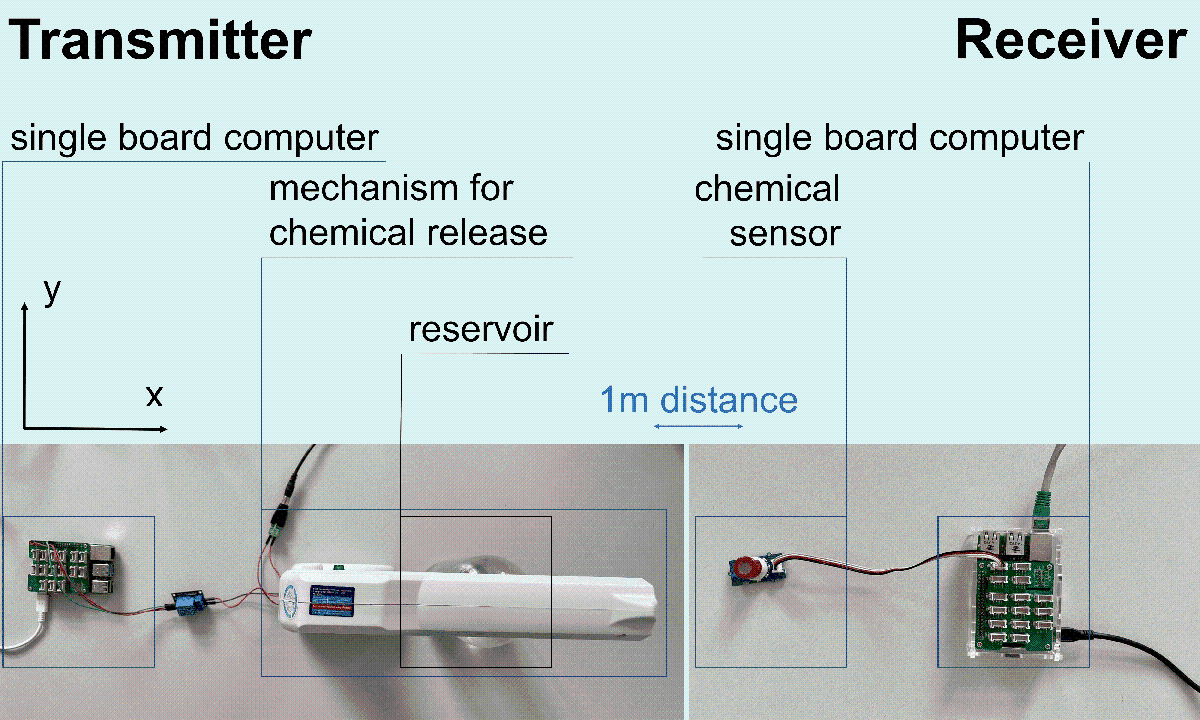

Fig. 1: Experimental Testbed used for MC as developed in [[1]](http://dx.doi.org/10.1109/BalkanCom55633.2022.9900720).

clear all;
close all;
clc;

### Parameters

sampling_time=0.1;%according to the description in [2]
fontsize=15; %for plotting
total_bits_plot=5; %for plotting
select_measurement=3;%select the column to plot between 2 and 41.
total_bits=10^5;
T_b=3; %bit duration in seconds
r_int=5;%amount of interference
%in the line below uncomment the value of 0.1835 for an SNR of 20dB, when
%A_tt=1, the SNR yields 27.5dB
A_tt=1;%0.1835;%artificial attenuation value to guarantee SNR=20dB

### Loading the Dataset

**Description**: This code produces a random emission of pulses with the Poisson distribution of the channel model. The received pulses are rendered with the recorded pulse from the testbed in Fig. 1.

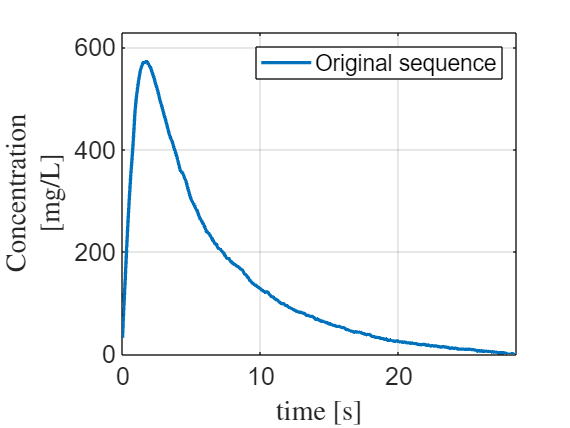

SNR=27.5


Dataset

### Plotting Dataset

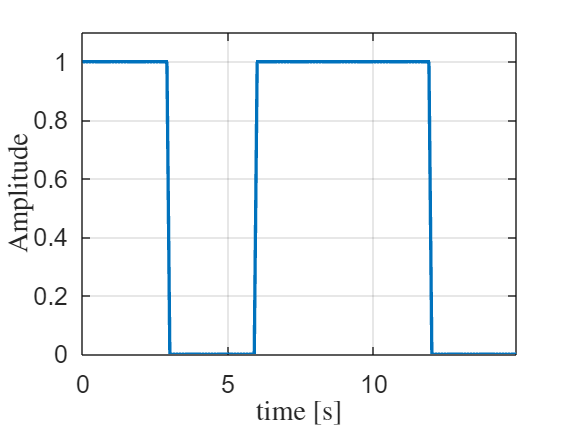

figure;
time=(0:ceil(T_b/sampling_time)*total_bits_plot-1)*sampling_time;
plot(time,Tx_pulses(1:length(time)),'LineWidth',2); grid on; 
xlabel('time [s]','Interpreter','latex');
ylabel({'Amplitude'},'Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 time(end) 0 1.1*max(Tx_pulses(1:length(time)))]);

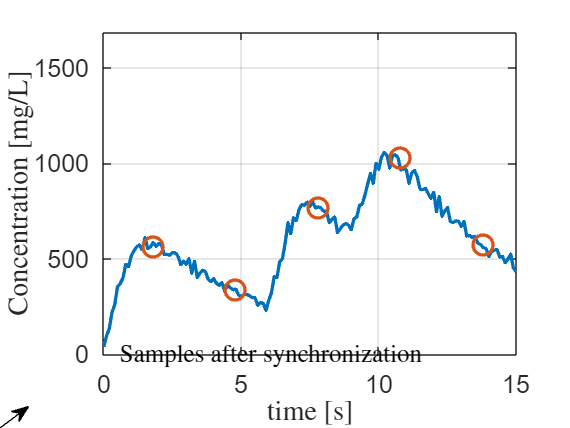


figure;
time=(0:ceil(T_b/sampling_time)*total_bits_plot)*sampling_time;
plot(time,seq_Rx(1:length(time)),'LineWidth',2); grid on; hold on;
plot(synch*sampling_time,seq_Rx(synch),'o','LineWidth',2,'MarkerSize',12);
text(0.5,0.5,strcat('Samples after synchronization'),'Interpreter','latex','FontSize',fontsize);
annotation('arrow', [0 0.05], [0 0.05]);
xlabel('time [s]','Interpreter','latex');
ylabel({'Concentration [mg/L]'},'Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 time(end) 0 1.1*max(seq_Rx)]);

Illustrating the histogram between samples in one and zero

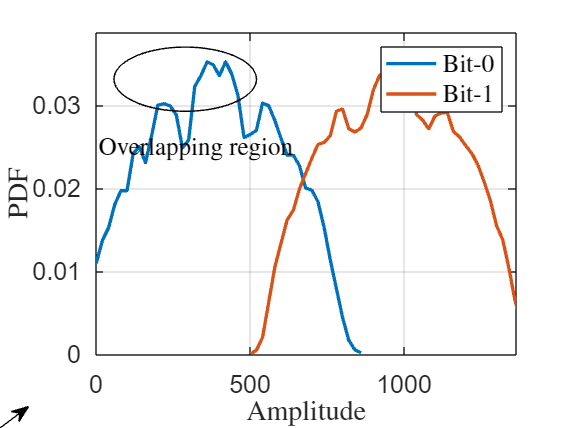

%histogram for the emission of zeros
[N_0,edges_0]=histcounts(Rx_samples(find(bits==0)));
%histogram for the emission of ones
[N_1,edges_1]=histcounts(Rx_samples(find(bits==1)));
figure;
plot(edges_0(1:end-1),N_0/sum(N_0),'LineWidth',2); hold on; grid on;
plot(edges_1(1:end-1),N_1/sum(N_1),'LineWidth',2); hold on; grid on;
text(0.025,0.025,strcat('Overlapping region'),'Interpreter','latex','FontSize',fontsize);
annotation('arrow', [0 0.05], [0 0.05]);
dim = [.2 .74 .25 .15];
annotation('ellipse',dim)
xlabel('Amplitude','Interpreter','latex');
ylabel({'PDF'},'Interpreter','latex');
legend({'Bit-0','Bit-1'},'Interpreter',"latex",'FontSize',fontsize);
set(gca,'FontSize',fontsize);
axis([0 max(Rx_samples(1:length(time))) 0 1.1*max(N_0)/sum(N_0)]);

### Train the bidirectional LSTM Network

Description: This section trains a bidirectional LSTM network using an architecture of three stacked LSTM layers as illustrated in Fig. 2

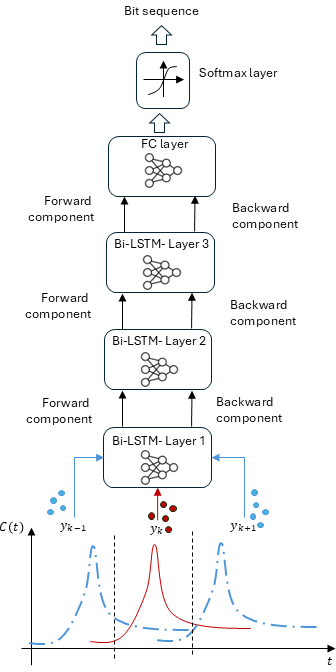

Fig. 2: Network architecture as follows from [3] and [4].

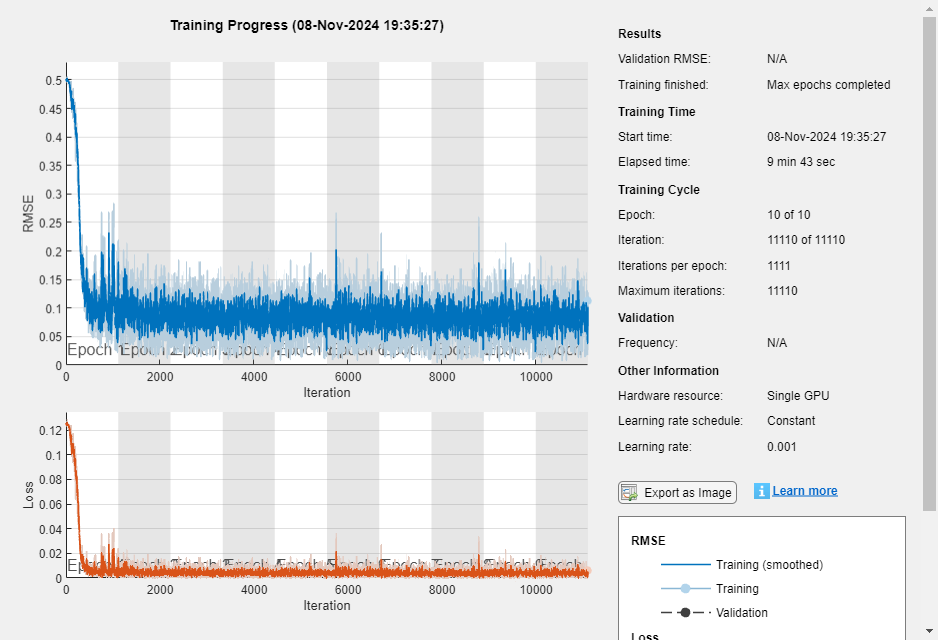

BiLSTM_training

save(strcat('trainedBiRNN','_Tb_',num2str(T_b),'s.mat'), 'net','traininfo','options');

#### Testing

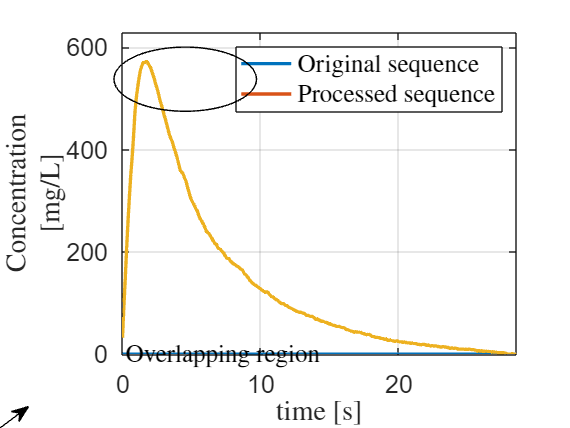

SNR=27.5


Dataset

predictedBits=predict(net,input_sequence);
%regenerate the Data set for a random transmission of bits

target_bits_vector=zeros(1,numel(predictedBits));
for i=1:numel(predictedBits)
    x1=(i-1)*input_length+1;
    x2=x1+input_length-1;
    predictedBits_vector(x1:x2)=predictedBits{i};    
    target_bits_vector(x1:x2)=target_bits{i};
end

decodedBits_vector=predictedBits_vector>0.5;
total_bit_errors=biterr(decodedBits_vector,target_bits_vector);
BER_u=total_bit_errors/length(target_bits_vector);
disp(['BER -> ',num2str(BER_u)])

BER -> 0.01127


disp(['T_b -> ',num2str(T_b),'s']);

T_b -> 3s


#### Plotting training performance

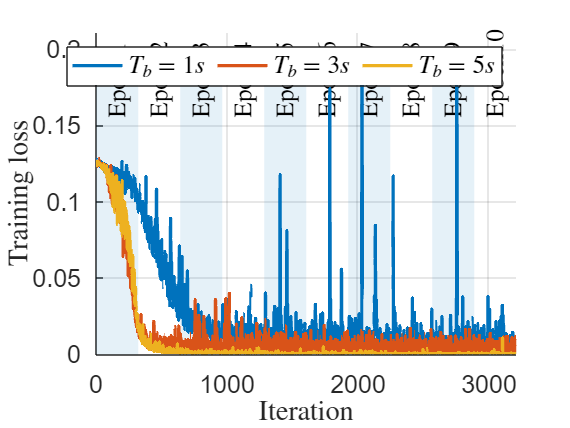

figure;
load trainedBiRNN_Tb_1s.mat
trainLoss = traininfo.TrainingLoss;
numBatchesPerEpoch = ceil(length(trainLoss)/options.MiniBatchSize);
%Printing the bars per Epoch
for i=1:options.MaxEpochs/2
    x1=(i-1)*2*numBatchesPerEpoch;
    x2=x1+numBatchesPerEpoch;
    p=patch([x1 x2 x2 x1],[0 0 0.2 0.2],[0 0.4470 0.7410],'EdgeColor','none');hold on;
    set(p,'FaceAlpha',0.1);
end
%Printing text per Epoch
for i=1:options.MaxEpochs
    x1=(i-1)*numBatchesPerEpoch;
    x2=x1+numBatchesPerEpoch;
    ht=text(x1+numBatchesPerEpoch/2, 0.8*max(trainLoss),{strcat('Epoch ',num2str(i))},'FontSize',fontsize,'Interpreter','latex');
    set(ht,'Rotation',90);
end

axis([0 length(trainLoss) 0 1.1*max(trainLoss)]);

p1=plot(trainLoss, 'LineWidth', 2);grid on; hold on
load trainedBiRNN_Tb_3s.mat
trainLoss = traininfo.TrainingLoss;
p2=plot(trainLoss, 'LineWidth', 2);
load trainedBiRNN_Tb_5s.mat
trainLoss = traininfo.TrainingLoss;
p3=plot(trainLoss, 'LineWidth', 2);

xlabel('Iteration','Interpreter','latex');
ylabel('Training loss','Interpreter','latex');
legend([p1,p2,p3],{'$T_b=1s$','$T_b=3s$','$T_b=5s$'},'Interpreter',"latex",'FontSize',fontsize,'NumColumns',3);
set(gca,'FontSize',fontsize);

### Deploy the bidirectional LSTM Network

**Description: ** This section deploys the LSTM network and evaluate the BER for various bit durations. For deployment, we use pre-trained bidirectional LSTM networks for the bit durations 1, 2, 3, 4, 5, 6 seconds. The deployed network implements a sliding architecture as described in Fig. 2 as follows from [3, Sec. 3.2].

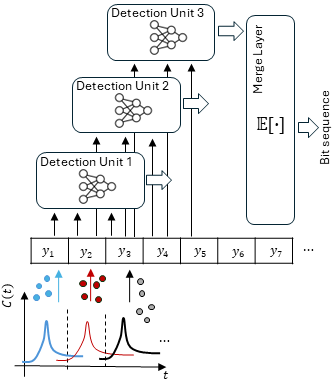

Fig. 2: Sliding bidirectional RNN [3, Sec. 3.2].

T_b_vector=[1,2,3,4,5,6]; %bit duration of pre-trained networks
BER=zeros(1,length(T_b_vector));
total_bits=10^6;
for k=1:length(T_b_vector)
    T_b=T_b_vector(k);
    load(strcat('trainedBiRNN_Tb_',num2str(k),'s.mat')); %load pre-trained network

#### **Create Dataset for testing**

    Dataset
    %transforming the input sequence to a vector
    input_sequence_vector=zeros(1,numel(input_sequence));
    input_sequence_3_vector=zeros(1,numel(input_sequence));
    for i=1:numel(input_sequence)
        x1=(i-1)*input_length+1;
        x2=x1+input_length-1;
        input_sequence_vector(x1:x2)=input_sequence{i};
    end
    %conforming the cell for the input sequences 2 and 3
    input_sequence_2=cell(numel(input_sequence)-1,1);
    input_sequence_3=cell(numel(input_sequence)-1,1);
    for i=1:numel(input_sequence)-1
        x1=(i-1)*input_length+1+1;
        x2=x1+input_length-1;
        input_sequence_2{i}=input_sequence_vector(x1:x2);
        x3=x1+1;
        x4=x2+1;
        input_sequence_3{i}=input_sequence_vector(x3:x4);
    end

#### Prediction

SNR=27.5


BER -> 0.01095


T_b -> 1s


SNR=27.5


BER -> 0.001868


T_b -> 2s


SNR=27.5


BER -> 0.00091901


T_b -> 3s


SNR=27.5


BER -> 0.00029


T_b -> 4s


SNR=27.5


BER -> 2e-06


T_b -> 5s


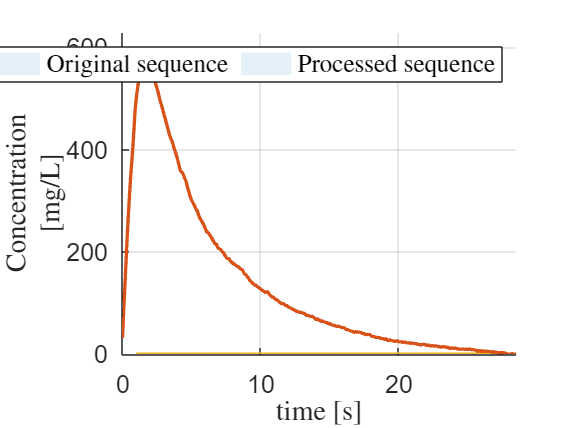

SNR=27.5


BER -> 1e-06


T_b -> 6s


    %deployment of the three detection units as in Fig. 2
    predictedBits_Unit_1 = predict(net, input_sequence);
    predictedBits_Unit_2 = predict(net, input_sequence_2);
    predictedBits_Unit_3 = predict(net, input_sequence_3);
    
    %Merge Layer
    %storing the results into a vector array
    predictedBits_Unit_1_vector=zeros(1,numel(predictedBits_Unit_3));
    predictedBits_Unit_2_vector=zeros(1,numel(predictedBits_Unit_3));
    predictedBits_Unit_3_vector=zeros(1,numel(predictedBits_Unit_3));
    target_bits_vector=zeros(1,numel(predictedBits_Unit_3));
    for i=1:numel(predictedBits_Unit_3)
        x1=(i-1)*input_length+1;
        x2=x1+input_length-1;
        predictedBits_Unit_1_vector(x1:x2)=predictedBits_Unit_1{i};
        predictedBits_Unit_2_vector(x1:x2)=predictedBits_Unit_2{i};
        predictedBits_Unit_3_vector(x1:x2)=predictedBits_Unit_3{i};
        target_bits_vector(x1:x2)=target_bits{i};
    end
    %Merging the result
    predictedBits=(predictedBits_Unit_1_vector+...
                   horzcat(0,predictedBits_Unit_2_vector(1:end-1))+...
                   horzcat([0,0],predictedBits_Unit_3_vector(1:end-2)))/2;
    
    decodedBit=predictedBits>0.5;
    total_bit_errors=biterr(decodedBit(1:end-2),target_bits_vector(1:end-2));
    BER(k)=total_bit_errors/length(target_bits_vector);
    disp(['BER -> ',num2str(BER(k))])
    disp(['T_b -> ',num2str(T_b),'s']);
end


save 'BER_vector.mat' BER T_b_vector total_bits;

#### Plotting the BER

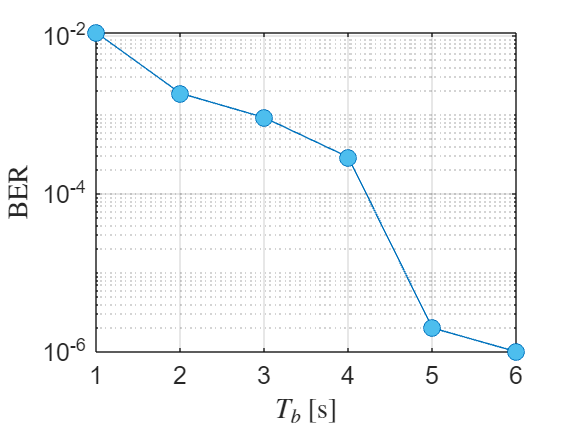

figure;
semilogy(T_b_vector,BER,'o-','MarkerSize',10,'MarkerFaceColor',"#4DBEEE",'MarkerEdgeColor',"#0072BD");grid on;
xlabel('$T_b$ [s]','Interpreter','latex');
ylabel({'BER'},'Interpreter','latex');
set(gca,'FontSize',fontsize);

%axis([0 max(Rx_samples(1:length(time))) 0 1.1*max(N_0)/sum(N_0)]);

### References

[1] P. Hofmann, J. Torres Gómez, F. Dressler, and F. H. P. Fitzek, “Testbed-based Receiver Optimization for SISO Molecular Communication Channels,” in 5th IEEE International Balkan Conference Communications and Networking (BalkanCom 2022), Sarajevo, Bosnia and Herzegovina: IEEE, Aug. 2022, pp. 120–125.

[2] Pit Hofmann, Jorge Torres Gómez, Frank H. P. Frank H.P. , Falko Dressler, April 27, 2023, "Dataset for Macroscale Molecular Communication Testbed", IEEE Dataport, doi: [https://dx.doi.org/10.21227/ytkm-xp81.](https://dx.doi.org/10.21227/ytkm-xp81.)

[3] N. Farsad and A. Goldsmith, “Detection Algorithms for Communication Systems Using Deep Learning,” arXiv, cs.LG, Jul. 2017.

[4] N. Farsad and A. Goldsmith, “Sliding Bidirectional Recurrent Neural Networks for Sequence Detection in Communication Systems,” in IEEE International Conference on Acoustics, Speech and Signal Processing (ICASSP 2018), Calgary, Canada: IEEE, Apr. 2018.